# Identify a continuous-time transfer function from a step response (with built-in matlab functions)

The first part of this script carries out the same steps as step002-open-loop-step-response/matlab/plotStepResponses.mlx.

## Read and plot the recorded data

The filename below belongs to the file with the step response experiment data. The step response data was recorded for input steps of +5 and -5 degrees. This value is fixed in the microcontroller code for the step response experiment, and it needs to be set here by hand. We also need to copy the time step (5ms= 0.005s) used in the arduino sketch. 

clear all;
close all; 
filename= "../../step002-open-loop-step-response/arduino/record_open_loop_step_response_data_for_matlab/data_for_matlab.txt"; 
uStep= 5; % deg, degrees
delta_t= 0.005; % seconds

We are now ready to read the data and to extract the time points and output values from it.

data = readtable(filename); 
tData = data{:, 1}'; % note transpose operator
yData = data{:, 2}';
omegaData = data{:, 3}';
t0= tData(1);
numpoints= length(yData);

We need to divide all time data by 1e6 to to convert microseconds to seconds. 

tData= tData* 1e-6; 

We first plot the entire set of recorded data, which contains more than one step response. 

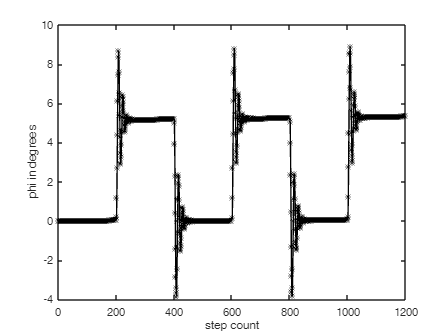

figure(); 
plot(yData, '-*', 'Color', 'black'); 
xlabel("step count");
ylabel("phi in degrees"); 

We now select a single step response to work with. Since the arduino generates a step input every 200 timesteps (which corresponds to a second for the sample time of 5ms), we can select steps 200 to 400. Actually, 200 to 300 suffice, since a new steady state has been reached after 100 steps. Play with these numbers to check if we picked a good interval. (Try 195 to 250, for example. Also try 199 to 250 and 201 to 250.)

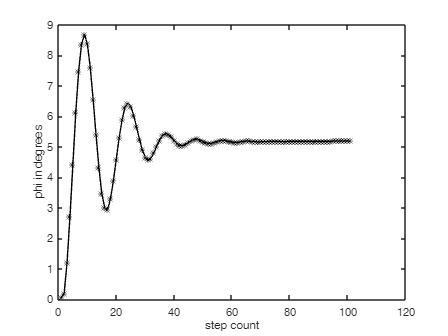

kstart= 200;
kstop= 300; 
figure();
plot(yData(kstart:kstop), '-*', 'Color', 'black'); 
xlabel("step count"); 
ylabel("phi in degrees"); 

Having selected an appropriate interval of steps, we can discard all other data. We can also reset the time of the first data point to be $t=0$ seconds.

Let's also include the input signal for comparison.

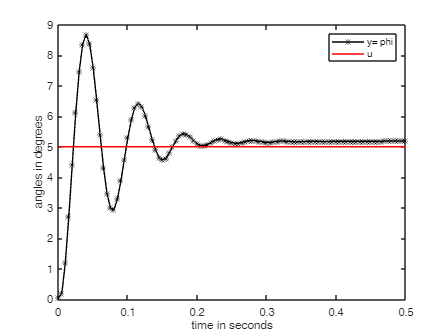

figure(); 
tData= tData(kstart:kstop)- tData(kstart); 
yData= yData(kstart:kstop); 
omegaData=omegaData(kstart:kstop);
plot(tData, yData, '-*', 'Color', 'black');
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 

Note that the $y$ may reach a new steady state value that is not equal to the input step. This must be accounted for with a static gain $K \ne 1$ in the transfer function. The output $y$ and input step may even have opposite signs, which can be accounted for by $K< 0$.

## Identification 

Fortunately, there exists a built-in matlab function (`tfest `for "transfer function estimation") that determines a transfer function from our recorded time series data. We need to fix the order of the denominator and denominator of the transfer function. These two numbers read "2" and "0" for the order of the denominator and numerator, respectively, because the polynomial in the denominator and numerator of our target transfer function


$$G(s)= \frac{K\omega_0}{s^2+ 2 D \omega_0 s+ \omega_0^2}$$


have order 2 and 0, respectively. We know these orders, because we were able to construct a reasonable transfer function in step002 by assuming the system to be a second order system (with constant numerator). 

identData= iddata(yData', uData', delta_t); 
transferFunction= tfest(identData, 2, 0)

transferFunction =
  From input "u1" to output "y1":
          7269
  --------------------
  s^2 + 26.72 s + 7003
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "identData".
Fit to estimation data: 87.79%                        
FPE: 0.02378, MSE: 0.02153                            
 
Model Properties


Matlab may issue a warning if `tfest` does not detect a steady state before the step. Try to adjust `kstart` selected in the previous section of this script to avoid this warning. 

The transfer function can now be used to determine a step response. Remember our input step had an amplitude `uStep`, while the `step()` command calculates the *unit* step response (assuming `uStep=1`, which is not the case unless you set the angular step to be 1 degree in the arduino code). Since the system is linear, we can simply mutiply the output `ySim` by `uStep`. 

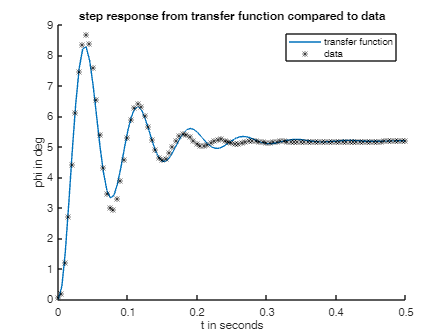

[ySim, tSim, ~]= step(transferFunction, tData(end)); 

figure(); 
figTitle= "step response from transfer function compared to data";
title(figTitle);
hold on; 
plot(tSim, ySim* uStep);
plot(tData, yData, '*', 'Color', 'black');
xlabel('t in seconds');
ylabel('phi in deg'); 
legend('transfer function', 'data'); 
hold off; 

## Transforming into a state-space system

Let us convert the second-order transfer function into a state-space system. Recall our transfer function reads $G(s)= \frac{K\omega_0}{s^2+2 D \omega_0 s+ \omega_0^2}$. It is convenient to rewrite it as 

$G(s)= \frac{b_0}{a_2 s^2+ a_1 s+ a_0}$, 

where $b_0= K\omega_0$, $a_2= 1$,$a_1= 2 D \omega_0$, $a_0= \omega_0^2$ merely are abbreviations. Applying the inverse Laplace-transform to this transfer function yields 

$\ddot{\varphi}+ a_1 \dot{\varphi}+ a_0 \varphi= b_0 u$, 

where we assume all initial conditions to be zero, and where $y= \varphi$ is our output.

Defining $\omega= \dot{\varphi}$, substituing $\dot{\varphi}$ and $\dot{\omega}= \ddot{\varphi}$ into the second-order differential equation and rearranging yields

$\dot{\varphi}= \omega$ and


$$\dot{\omega}= -a_0 \varphi -a_1\omega + b_0 u$$


or equivalently

$\left[\begin{array}{c} \dot{\varphi} \\ \dot{\omega}\end{array}\right]= \left[\begin{array}{cc} 0 & 1 \\ -a_0 & -a_1 \end{array}\right] \left[\begin{array}{c} \varphi \\ \omega\end{array}\right]+ \left[\begin{array}{c} 0 \\ b_0\end{array}\right] u$.

Let us extract the coefficients $a_0$, $a_1$ and $b_0$ from the transfer function and make  sure that $a_2= 1$, which we assumed throughout:

denominator= transferFunction.Denominator;
a2= denominator(1),a1= denominator(2), a0= denominator(3)

a2 = 1

a1 = 26.7183

a0 = 7.0031e+03

numerator= transferFunction.Numerator;
b0= numerator(1)

b0 = 7.2691e+03

if abs(a2 - 1) > 1e-10
    error('Coefficient a2 is expected to be 1, but got %.5g instead.', a2);
end

Finally, we can construct the matrices

$A= \left[\begin{array}{cc} 0 & 1 \\ -a_0 & -a_1 \end{array}\right]$and $B= \left[\begin{array}{c} 0 \\ b_0\end{array}\right]$:

A= [0 1; -a0 -a1], B= [0; b0]

A = 1.0e+03 *

         0    0.0010
   -7.0031   -0.0267


B = 1.0e+03 *

         0
    7.2691


We can check our result by comparing simulation results for the state-space system to results obtained with the transfer function and to the original experimental data.

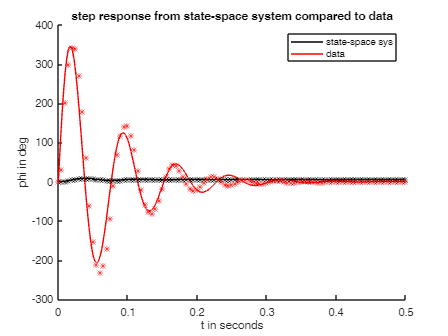

uODE = @(t) uStep;  % constant input with same amplitude as input step 
x0ODE = [0; 0];     % zero initial conditions phi= omega= 0.

dxdt = @(t, x) A*x + B*uODE(t); % right hand side of ODEs

tspan = [0 tData(end)];  % integration time interval
[tODE, xODE] = ode45(dxdt, tspan, x0ODE);

% plot
figure(); 
figTitle= "step response from state-space system compared to data";
title(figTitle);

hold on;
plot(tODE, xODE(:,1), 'Color', 'black');
plot(tODE, xODE(:,2), 'r');
plot(tData, yData, '*', 'Color', 'black');
plot(tData, omegaData, 'r*');
xlabel('t in seconds');
ylabel('phi in deg'); 
legend('state-space sys', 'data');
hold off;

## LQR

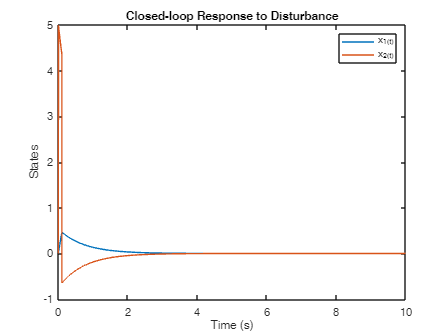

Q = diag([10 0.001]);   % Penalize both states equally
R = 1;        % Penalize input effort

K = lqr(A, B, Q, R);

% d = 5;
%d = @(t) 
A_cl = A - B*K;
B_d = B;        % disturbance enters through same channel
x0 = [0; 0];    % initial state
tspan = [0 10]; % simulation time

dxdt = @(t, x) A_cl*x + B_d*5*(t >= 0 & t <= 1/10);

[t, x] = ode45(dxdt, tspan, x0);

plot(t, x)
xlabel('Time (s)')
ylabel('States')
legend('x_1(t)', 'x_2(t)')
title('Closed-loop Response to Disturbance')

## Try without initial angular velocity but initial condition for the angle

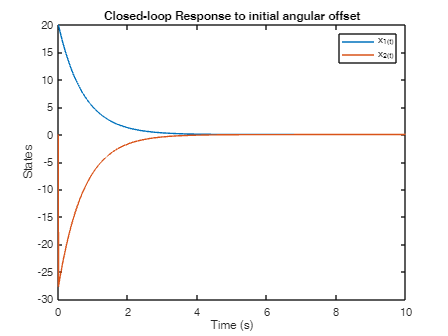

A_cl = A - B*K;
B_d = B;        % disturbance enters through same channel
x0 = [20; 0];    % initial state
tspan = [0 10]; % simulation time

dxdt = @(t, x) A_cl*x;

[t, x] = ode45(dxdt, tspan, x0);

plot(t, x)
xlabel('Time (s)')
ylabel('States')
legend('x_1(t)', 'x_2(t)')
title('Closed-loop Response to initial angular offset')

## Export results to files, for use with other live scripts

%identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction= transferFunction;
%identifyTransferFunctionContinuousTimeResults.delta_t= delta_t;
%identifyTransferFunctionContinuousTimeResults.uStep= uStep;
%identifyTransferFunctionContinuousTimeResults.tData= tData;
%identifyTransferFunctionContinuousTimeResults.yData= yData; 
%save("identifyTransferFunctionContinuousTimeResults.mat", 'identifyTransferFunctionContinuousTimeResults');